clc
clear

pitotDataDir = dir('Aero Lab Windtunnel Calibration\Aero Lab 1 - 2019 Group Data\VelocityVoltageData\PitotProbeToPressureTransducer\');
pitot_long_name1 = strcat(pitotDataDir(3).folder,'\',pitotDataDir(3).name);
pitotData1 = load(pitot_long_name1);
R=287;

rhoWater = 1000; % kg/m^3
gravity = 9.81; % m/s^2
T = mean(pitotData1(:,2));
p_atm = mean(pitotData1(:,1));

%airspeeds for pitot tube (pitot static to pressure transducer)
p_airspeed1_1=sqrt(2.*pitotData1(1:500,3).*R.*pitotData1(1:500,2)./pitotData1(1:500,1));
p_airspeed1_3=sqrt(2.*pitotData1(501:1000,3).*R.*pitotData1(501:1000,2)./pitotData1(501:1000,1));
p_airspeed1_5=sqrt(2.*pitotData1(1001:1500,3).*R.*pitotData1(1001:1500,2)./pitotData1(1001:1500,1));
p_airspeed1_7=sqrt(2.*pitotData1(1501:2000,3).*R.*pitotData1(1501:2000,2)./pitotData1(1501:2000,1));
p_airspeed1_9=sqrt(2.*pitotData1(2001:2500,3).*R.*pitotData1(2001:2500,2)./pitotData1(2001:2500,1));
p_as_avg_1 = mean(p_airspeed1_1);
p_as_avg_3 = mean(p_airspeed1_3);
p_as_avg_5 = mean(p_airspeed1_5);
p_as_avg_7 = mean(p_airspeed1_7);
p_as_avg_9 = mean(p_airspeed1_9);
deltaP_p_1 = mean(pitotData1(1:500,3));
deltaP_p_3 = mean(pitotData1(501:1000,3));
deltaP_p_5 = mean(pitotData1(1001:1500,3));
deltaP_p_7 = mean(pitotData1(1501:2000,3));
deltaP_p_9 = mean(pitotData1(2001:2500,3));
p_error_1 = totalError(deltaP_p_1, T, p_atm);
p_error_3 = totalError(deltaP_p_3, T, p_atm);
p_error_5 = totalError(deltaP_p_5, T, p_atm);
p_error_7 = totalError(deltaP_p_7, T, p_atm);
p_error_9 = totalError(deltaP_p_9, T, p_atm);

venturiDataDir = dir('Aero Lab Windtunnel Calibration\Aero Lab 1 - 2019 Group Data\VelocityVoltageData\VenturiTubeToPressureTransducer\');
venturi_long_name1 = strcat(venturiDataDir(3).folder,'\',venturiDataDir(3).name);
venturiData1 = load(venturi_long_name1);
areaR = (1-(1/9.5)^2);

%venturi airspeeds for tube 1 (venturi to pressure transducer)
v_airspeed1_2=sqrt((2.*venturiData1(1:500,3).*R.*venturiData1(1:500,2))./(venturiData1(1:500,1)).*areaR);
v_airspeed1_4=sqrt((2.*venturiData1(501:1000,3).*R.*venturiData1(501:1000,2))./(venturiData1(501:1000,1)).*areaR);
v_airspeed1_6=sqrt((2.*venturiData1(1001:1500,3).*R.*venturiData1(1001:1500,2))./(venturiData1(1001:1500,1)).*areaR);
v_airspeed1_8=sqrt((2.*venturiData1(1501:2000,3).*R.*venturiData1(1501:2000,2))./(venturiData1(1501:2000,1)).*areaR);
v_airspeed1_10=sqrt((2.*venturiData1(2001:2500,3).*R.*venturiData1(2001:2500,2))./(venturiData1(2001:2500,1)).*areaR);
v_as_avg_2 = mean(v_airspeed1_2);
v_as_avg_4 = mean(v_airspeed1_4);
v_as_avg_6 = mean(v_airspeed1_6);
v_as_avg_8 = mean(v_airspeed1_8);
v_as_avg_10 = mean(v_airspeed1_10);
deltaP_v_2 = mean(venturiData1(1:500,3));
deltaP_v_4 = mean(venturiData1(501:1000,3));
deltaP_v_6 = mean(venturiData1(1001:1500,3));
deltaP_v_8 = mean(venturiData1(1501:2000,3));
deltaP_v_10 = mean(venturiData1(2001:2500,3));
v_error_2 = totalError(deltaP_v_2, T, p_atm);
v_error_4 = totalError(deltaP_v_4, T, p_atm);
v_error_6 = totalError(deltaP_v_6, T, p_atm);
v_error_8 = totalError(deltaP_v_8, T, p_atm);
v_error_10 = totalError(deltaP_v_10, T, p_atm);

% Venturi tube to water monometer
manometerError = 12.442; % [Pa]
m_v_diffP_1_5 = (0.1*0.0254*rhoWater*gravity);
m_v_diffP_3_5 = (0.6*0.0254*rhoWater*gravity);
m_v_diffP_5_5 = (1.8*0.0254*rhoWater*gravity);
m_v_diffP_7_5 = (3.4*0.0254*rhoWater*gravity);
m_v_diffP_9_5 = (5.5*0.0254*rhoWater*gravity);
m_v_airspeed_1_5 =  sqrt(2*m_v_diffP_1_5*R*T/(p_atm*areaR));
m_v_airspeed_3_5 =  sqrt(2*m_v_diffP_3_5*R*T/(p_atm*areaR));
m_v_airspeed_5_5 =  sqrt(2*m_v_diffP_5_5*R*T/(p_atm*areaR));
m_v_airspeed_7_5 =  sqrt(2*m_v_diffP_7_5*R*T/(p_atm*areaR));
m_v_airspeed_9_5 =  sqrt(2*m_v_diffP_9_5*R*T/(p_atm*areaR));
m_v_error_1_5 = manometerTotalError(m_v_diffP_1_5, T, p_atm);
m_v_error_3_5 = manometerTotalError(m_v_diffP_3_5, T, p_atm);
m_v_error_5_5 = manometerTotalError(m_v_diffP_5_5, T, p_atm);
m_v_error_7_5 = manometerTotalError(m_v_diffP_7_5, T, p_atm);
m_v_error_9_5 = manometerTotalError(m_v_diffP_9_5, T, p_atm);

% pitot static probe to water monometer
m_p_diffP_0_5 = (0.05*0.0254*rhoWater*gravity);
m_p_diffP_2_5 = (0.25*0.0254*rhoWater*gravity);
m_p_diffP_4_5 = (1.2*0.0254*rhoWater*gravity);
m_p_diffP_6_5 = (2.6*0.0254*rhoWater*gravity);
m_p_diffP_8_5 = (4.4*0.0254*rhoWater*gravity);
m_p_airspeed_0_5 =  sqrt(2*m_p_diffP_0_5*R*T/(p_atm));
m_p_airspeed_2_5 =  sqrt(2*m_p_diffP_2_5*R*T/(p_atm));
m_p_airspeed_4_5 =  sqrt(2*m_p_diffP_4_5*R*T/(p_atm));
m_p_airspeed_6_5 =  sqrt(2*m_p_diffP_6_5*R*T/(p_atm));
m_p_airspeed_8_5 =  sqrt(2*m_p_diffP_8_5*R*T/(p_atm));
m_p_error_0_5 = manometerTotalError(m_p_diffP_0_5, T, p_atm);
m_p_error_2_5 = manometerTotalError(m_p_diffP_2_5, T, p_atm);
m_p_error_4_5 = manometerTotalError(m_p_diffP_4_5, T, p_atm);
m_p_error_6_5 = manometerTotalError(m_p_diffP_6_5, T, p_atm);
m_p_error_8_5 = manometerTotalError(m_p_diffP_8_5, T, p_atm);

Pitot_PT_AS = [p_as_avg_1,p_as_avg_3,p_as_avg_5,p_as_avg_7,p_as_avg_9];
Pitot_PT_V = [1,3,5,7,9];
Pitot_PT_E = [p_error_1,p_error_3,p_error_5,p_error_7,p_error_9];
Pitot_PT_Eav = mean(Pitot_PT_E)

Pitot_PT_Eav = 5.7789


Venturi_PT_AS = [v_as_avg_2,v_as_avg_4,v_as_avg_6,v_as_avg_8,v_as_avg_10];
Venturi_PT_V = [2,4,6,8,10];
Venturi_PT_E = [v_error_2,v_error_4,v_error_6,v_error_8,v_error_10];
Venturi_PT_Eav = mean(Venturi_PT_E)

Venturi_PT_Eav = 5.8347


Venturi_WM_AS = [m_v_airspeed_1_5,m_v_airspeed_3_5,m_v_airspeed_5_5,m_v_airspeed_7_5,m_v_airspeed_9_5];
Venturi_WM_V = [1.5,3.5,5.5,7.5,9.5];
Venturi_WM_E = [m_v_error_1_5,m_v_error_3_5,m_v_error_5_5,m_v_error_7_5,m_v_error_9_5];
Venturi_WM_Eav = mean(Venturi_WM_E)

Venturi_WM_Eav = 1.1881


Pitot_WM_AS = [m_p_airspeed_0_5,m_p_airspeed_2_5,m_p_airspeed_4_5,m_p_airspeed_6_5,m_p_airspeed_8_5];
Pitot_WM_V = [0.5,2.5,4.5,6.5,8.5];
Pitot_WM_E = [m_p_error_0_5,m_p_error_2_5,m_p_error_4_5,m_p_error_6_5,m_p_error_8_5];
Pitot_WM_Eav = mean(Pitot_WM_E)

Pitot_WM_Eav = 1.3609

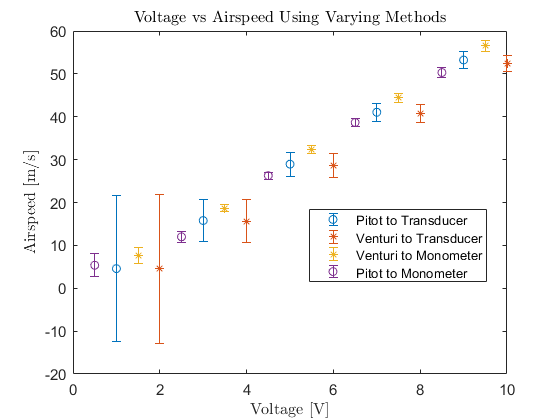


errorbar(Pitot_PT_V,Pitot_PT_AS,Pitot_PT_E,"o")
% plot(Pitot_PT_V,Pitot_PT_AS,"o","LineWidth",1)
hold on
set(0,'defaultTextInterpreter','latex')
set(gca,'FontSize',11)
title("Voltage vs Airspeed Using Varying Methods")
xlabel("Voltage [V]")
ylabel("Airspeed [m/s]")
% plot(Venturi_PT_V,Venturi_PT_AS,"o","LineWidth",1)
% plot(Venturi_WM_V,Venturi_WM_AS,"*","LineWidth",1)
% plot(Pitot_WM_V,Pitot_WM_AS,"*","LineWidth",1)

errorbar(Venturi_PT_V,Venturi_PT_AS,Venturi_PT_E,"*")
errorbar(Venturi_WM_V,Venturi_WM_AS,Venturi_WM_E,"*")
errorbar(Pitot_WM_V,Pitot_WM_AS,Pitot_WM_E,"o")
legend("Pitot to Transducer","Venturi to Transducer","Venturi to Monometer","Pitot to Monometer","Location","best")
hold off

function error = totalError(pDiff, T, p_atm)
R = 287;
Terror = 0.25;
Pdiff_error = 68; % [Pa]
Patm_error = .015 * 220000; % [Pa]

errorVdP = (((R*T)/(p_atm*sqrt(2*R*T*pDiff/p_atm)))*Pdiff_error)^2;
errorVPatm = (((-pDiff*R*T)/((p_atm^2)*sqrt(2*R*T*pDiff/p_atm)))*Patm_error)^2;
errorVTatm = (((R*pDiff)/(p_atm*sqrt(2*R*T*pDiff/p_atm)))*Terror)^2;
error = sqrt(errorVdP+errorVPatm+errorVTatm);
end

function error = manometerTotalError(pDiff, T, p_atm)
R = 287;
Terror=0.25;
mPdiff_error = 12.442; % [Pa]
Patm_error = .015 * 220000; % [Pa]

errorVdP = (((R*T)/(p_atm*sqrt(2*R*T*pDiff/p_atm)))*mPdiff_error)^2;
errorVPatm = (((-pDiff*R*T)/((p_atm^2)*sqrt(2*R*T*pDiff/p_atm)))*Patm_error)^2;
errorVTatm = (((R*pDiff)/(p_atm*sqrt(2*R*T*pDiff/p_atm)))*Terror)^2;
error = sqrt(errorVdP+errorVPatm+errorVTatm);
end